clc
clear

k=1; % W/m.k

h1=20; % W/m^2.k
h2=10;
h3=40;

T1=20+273; % Kelvin
T2=30+273;
T3=20+273;
Tg=100+273; % Gas temperature
T4=70+273; % Left wall temperature

x=0.1; % meter
y=0.1;
z=1;

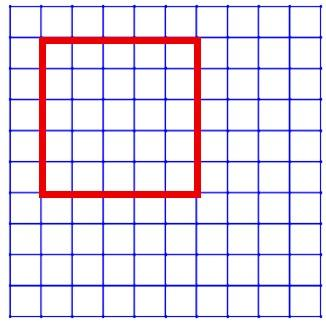

TT=zeros(11);
%Left wall
TT(:,1)=T4;
%Inner chamber
TT(2:7,2:7)=Tg;

T=zeros(121,1);
A=zeros(121);
C=zeros(121,1);
for n=1:11
    for m=1:11
        i=(n-1)*11+m;
        f=0; % flag variable
        if TT(n,m)==0
            % Upper wall nodes 2-10
            if n==1 && m<11
                A(i,i)=-(2*k+x*h2);
                A(i,i-1)=k/2;
                A(i,i+1)=k/2;
                A(i,i+11)=k;
                C(i,1)=-h2*x*T2;
                f=1;
            end

            % Lower wall nodes 112-120
            if n==11 && m<11
                A(i,i)=-(2*k+x*h1);
                A(i,i-1)=k/2;
                A(i,i+1)=k/2;
                A(i,i-11)=k;
                C(i,1)=-h1*x*T1;
                f=1;
            end
                
            % Right wall nodes 22,33,44,55,66,77,88,99,110
            if m==11 && n<11 && n>1
                A(i,i)=-(2*k+y*h3);
                A(i,i-11)=k/2;
                A(i,i+11)=k/2;
                A(i,i-1)=k;
                C(i,1)=-h3*y*T3;
                f=1;
            end

            % Upper-right corner node 11
            if n==1 && m==11
                A(i,i)=-(k+(x/2)*(h2+h3));
                A(i,i-1)=k/2;
                A(i,i+11)=k/2;
                C(i,1)=-(h2*(x/2)*T2 + h3*(y/2)*T3);
                f=1;
            end
                
            % Lower-right corner node 121
            if n==11 && m==11
                A(i,i)=-(k+(x/2)*(h1+h3));
                A(i,i-1)=k/2;
                A(i,i-11)=k/2;
                C(i,1)=-(h1*(x/2)*T1 + h3*(y/2)*T3);
                f=1;
            end
            
            % All the nodes in the brick (only conduction)
            if f==0
                A(i,i)=-4;
                A(i,i-1)=1;
                A(i,i+1)=1;
                A(i,i-11)=1;
                A(i,i+11)=1;
            end

        else
            T(i)=TT(n,m);
            A(i,i)=1;
            C(i,1)=TT(n,m);
        end
    end
end

TK=A\C; %Solve for kelvin
TC=zeros(121,1); % Celsius
for j=1:121
    TC(j,1)=TK(j,1)-273;
end

Vis=zeros(11,11);
for i=1:11
    for j=1:11
        Vis(i,j)=TC((i-1)*11+j,1);
    end
end

% Calculate the total heat transfer of the outer boundary

% Four corners
q1= h2*(x/2)*z*(T4-T2); % Node 1 (corner)
q111= h1*(x/2)*z*(T4-T1); % Node 111 (corner)
q11= h2*(x/2)*z*(Vis(1,11)-T2) + h3*(y/2)*z*(Vis(1,11)-T3); % Node 11(corner)
q121= h1*(x/2)*z*(Vis(11,11)-T1) + h3*(y/2)*z*(Vis(11,11)-T3); % Node 121(corner)
q=q1+q11+q111+q121;

% 3 Sides (Up, Right, Down)
for i=2:10
    qup=h2*x*z*(Vis(1,i)-T2);
    qdown=h1*x*z*(Vis(11,i)-T1);
    qright=h3*y*z*(Vis(i,11)-T3);
    q=q+qup+qdown+qright;
end